# Lab 2 -- How to use Statistical Functions and plot Histograms in MATLAB

#### Lab Section 2

#### Team Members

#### Jonathan Sumner

#### Diego Lopez

#### Argenis Aquino

**Rachel DuBois**

### Team Lead

#### Jonathan Sumner

### **Objective:**

The objective of this activity is to gain experience using the statistical functions in MATLAB to process digital signals. 

###  **Intended Learning Outcomes: **

- Be able to use statistical functions in MATLAB to analyze data 

- Become familiar with using MATLAB commands: rand, max, min, mean, std 

- Use the histogram function to estimate and characterize the probability density function of random variable

- Analyze a dataset in terms of its signal to noise ratio

- Analyze the histogram of quantization noise for large and small signals relative to the quantization step size

### Procedure:

Follow the steps in each section of the Live script running each block as you go.  Be sure to answer the questions posed. You can answer these right in the text sections themselves.  You will submit your completed document as the MATLAB Live Script file and as an PDF file when you are completed.

## Part 1

Load the matlab datafile from myCourses "Lab2_Chapter2_Section1.mat" .  This will load two variables into the work space, 'sample' and 'signal'

clear
load data/Lab2_Chapter2_Section1.mat
[sample, signal]

ans =     1.0000   57.0897
    2.0000   60.9080
    3.0000   74.3197
    4.0000   62.3249
    5.0000   51.2235
    6.0000   45.5155
    7.0000   36.8009
    8.0000   39.8796
    9.0000   26.4516
   10.0000   20.4169


Press the Button below to Run the code in this section

### Step 1 Compute the Statistics

This file contains a variable called signal that has 730 samples.  Compute the maximum value (max), minimum value (min), average value (mean), standard deviation (std) and the variance ( square of the standard deviation) of the variable 'signal'. 

%  Create the variables below that represent the statistics of the variable signal
%
%  maxSignal = max(signal)
%  minSignal =
%  avgSignal =
%  stdSignal =
%  varSignal =

%  Solution -- Place your code here
maxSignal = max(signal)

maxSignal = 76.4106

minSignal = min(signal)

minSignal = 20.4169

avgSignal = mean(signal)

avgSignal = 48.1501

stdSignal = std(signal)

stdSignal = 8.3260

varSignal = var(signal)

varSignal = 69.3218

Press the Button below to Run your code in this section

### Step 2  Create a Data Table

Create a table in MATLAB to display the values.  Use the 'table' function in MATLAB.   I've created the first table for you.  You can use this as a template to create later tables.  Use the help feature of MATLAB to look up how to enter values in a table.  The values of a column must be a column vector.  Use the Properties 'RowName' and 'VariableNames' to add row names and column names respectively.  Note that the list of row names and variable names must be a MATLAB cell array which is a data type that is enclosed by curly braces.  For example a = { 'first', 'second', 'third'} is a cell array.

% Create a column vector with the values for the table.
% Each statistic occupies its own row in this vector.
valuesForTable = [maxSignal; minSignal; avgSignal; stdSignal; varSignal];

% Create the table, specifying row names and a variable name (column header).
statsTable = table(valuesForTable,...
    'RowNames',{'Maximum','Minimum','Average','Standard Deviation','Variance'},...
    'VariableNames',{'Values'});

% Display the table
disp(statsTable);

                          Values
                          ______

    Maximum               76.411
    Minimum               20.417
    Average                48.15
    Standard Deviation     8.326
    Variance              69.322



Press the Button below to Run the code in this section

### Step 3  Plot the Data

Plot the values of the varible 'signal' versus the variable 'sample'.  I have made the first plot for you.  Add a descriptive title,  and label the xaxis and the yaxis appropriately using the MATLAB commands 'title', 'xlabel' and 'ylabel' appropriately.  Turn on the grid

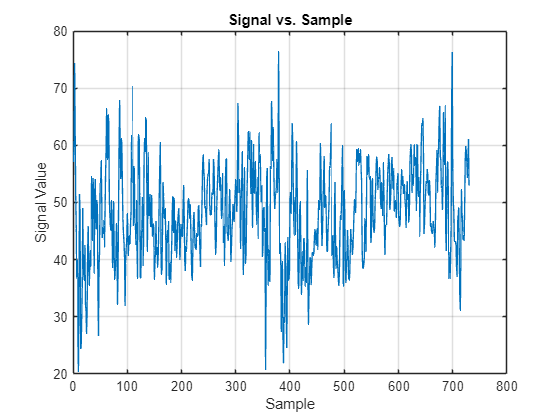

%  Plot the variable signal versus the variable sample.  Use the default line colors and style (blue and - )Use a larger
%  linewidth and turn on the grid

figure
plot(sample, signal, 'LineWidth',1)

% Add a descriptive title
title('Signal vs. Sample')

% Label the x-axis and y-axis
xlabel('Sample')
ylabel('Signal Value')

% Turn on the grid
grid on

Press the Button below to Run the code in this section

### Question 1

Anwer the following questions by typing directly in the text section of this Live Script.

Which statistical parameters can you estimate by just observing the samples on the graph?  Which ones can you not estimate?  Do the values that you estimate by observing the graph agree with the values that you computed?  Why or why not?

### Type your answer here:

You can roughly estimate the maximum, minimum, and mean by looking at the graph of the samples. However, you cannot reliably estimate the standard deviation or variance by eye. The visually guessed values usually do not match the computed statistics exactly, because human observation is imprecise compared to precise numerical calculations on all data points.

### Step 5  Create a Histogram

MATLAB has a function to create histograms of the data, 'histogram(y)'.  Use the MATLAB HELP to find more details on the function.

Use the MATLAB histogram function to plot the histogram of the signal.  Add a title, and label the x and y axes of the plot

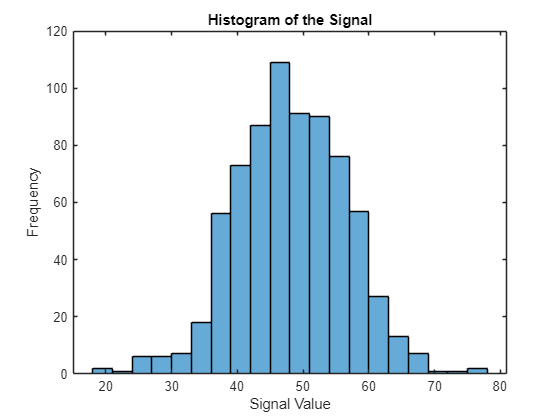

%  Plot a histogram of the signal data.


%  Solution -- Place your code 
figure
histogram(signal)
title('Histogram of the Signal')
xlabel('Signal Value')
ylabel('Frequency')

  Press the Button below to Run the code in this section

#### Question 2

What probability distribution best describes the data (uniform, triangular, normal, other)?  Type your answer below.

#### Type your answer here:

The data typically appears to follow a normal (Gaussian) distribution. This makes sense because many real-world or simulated measurement processes often converge to a bell-shaped distribution due to random influences.

## Part 2  Load Dataset 2

Load the matlab datafile from myCourses "Lab2_Chapter2_Section2.mat" .  This will load four variables into the work space, 'sample' and 'signal_1', 'signal_2', 'sumSignals'

%  Clear the workspace and load the data file
clear
load data/Lab2_Chapter2_Section2.mat
[sample, signal_1, signal_2, sumSignals]

ans =     1.0000   80.1875    3.9687   84.1562
    2.0000   79.6697    3.9136   83.5833
    3.0000   79.6080    3.1394   82.7475
    4.0000   80.4404    5.2124   85.6528
    5.0000   80.3575   11.4475   91.8049
    6.0000   80.2005    5.0002   85.2007
    7.0000   79.9836    3.8574   83.8410
    8.0000   79.5035    3.4783   82.9818
    9.0000   79.9984    6.2141   86.2125
   10.0000   80.1172    9.2031   89.3204


Press the Button below to Run the code in this section

### Step 1 Compute the Statistics

This file contains three variables.  The variables 'signal_1' and 'signal_2' and sumSignals have 730 samples each.  The variable 'sum_signals' is the sum of those two signals.  Compute the maximum value (max), minimum value (min), average value (mean), standard deviation (std) and the variance ( square of the standard deviation) of the variable 'signal'.  Repeat the calculations for signal 2.  Compute the same statistics for the variable sumSignals that is the sum of signal_1 and signal_2.

%  Create the variables below that represent the statistics of the variable signal
%
%  maxSignal_1 =
%  minSignal_1 =
%  avgSignal_1 =
%  stdSignal_1 =
%  varSignal_1 
%
%  Create another set for signal_2 and for the sum of the signals

% Statistics for signal_1
maxSignal_1 = max(signal_1);
minSignal_1 = min(signal_1);
avgSignal_1 = mean(signal_1);
stdSignal_1 = std(signal_1);
varSignal_1 = var(signal_1);

% Statistics for signal_2
maxSignal_2 = max(signal_2);
minSignal_2 = min(signal_2);
avgSignal_2 = mean(signal_2);
stdSignal_2 = std(signal_2);
varSignal_2 = var(signal_2);

% Statistics for sumSignals
maxSum      = max(sumSignals);
minSum      = min(sumSignals);
avgSum      = mean(sumSignals);
stdSum      = std(sumSignals);
varSum      = var(sumSignals);

Press the Button below to Run your code in this section

### Step 2  Create a Data Table

Create a table in MATLAB to display the computed statistics.  Use the code to create a table above as a template.  Copy, Paste and modify the code as needed.  Create a table that looks like the table in the figure below:

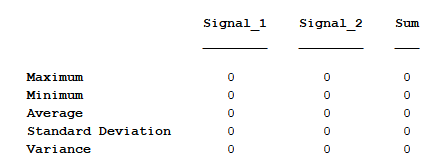

Use the 'table' function in MATLAB.   I've created the first column vector for you.  Create the other two and include the RowNames property and the VariableNames property.

% Create a column vector with the values for the table.
% Each value for the statistics is in one row

% Create column vectors of the statistics
valSig1 = [maxSignal_1; minSignal_1; avgSignal_1; stdSignal_1; varSignal_1];
valSig2 = [maxSignal_2; minSignal_2; avgSignal_2; stdSignal_2; varSignal_2];
valSum  = [maxSum;      minSum;      avgSum;      stdSum;      varSum];

% Create the table
statsTable = table(valSig1, valSig2, valSum, ...
    'RowNames', {'Maximum','Minimum','Average','Std_Dev','Variance'}, ...
    'VariableNames', {'Signal_1','Signal_2','Sum'});

% Display the table in Command Window
disp(statsTable)

                Signal_1    Signal_2     Sum  
                ________    ________    ______

    Maximum       80.499     12.989     93.424
    Minimum         79.5      3.009     82.644
    Average       80.008     7.9344     87.943
    Std_Dev       0.2885      2.945     2.9674
    Variance    0.083234     8.6732     8.8056



Press the Button below to Run the code in this section

### Step 3  Plot the Data

Create an individual plot of each variable signal_1, signal_2 and sumSignal.  Properly label the title and the axes.  Scale the y-axes for all three graphs from 0 to 100 using the 'ylim' function.  For example ylim( [yMIn,yMax] ) where yMin and yMax are the minimum and maximum y-values.  Having the same axes for graphs that you are going to compare is very helpful to the reader.  Turn the grid on for all three graphs.  Use the plotting code from above as a starting point.  Copy and Paste as needed.  Create a new figure for each plot.

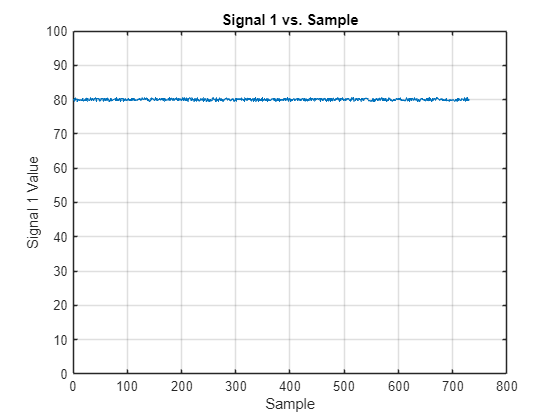

%  Plot the variables versus the variable sample.  Use the default line colors and style (blue and - )Use a larger
%  linewidth and turn on the grid

%  Solution -- Place your code to label the axes and title the graph

%  Signal 1
figure
plot(sample, signal_1, 'LineWidth', 1)
title('Signal 1 vs. Sample')
xlabel('Sample')
ylabel('Signal 1 Value')
ylim([0 100])  % Scale from 0 to 100 on the y-axis
grid on

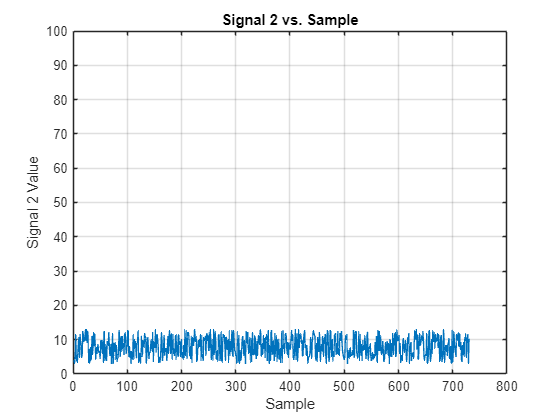

%  Signal 2
figure
plot(sample, signal_2, 'LineWidth', 1)
title('Signal 2 vs. Sample')
xlabel('Sample')
ylabel('Signal 2 Value')
ylim([0 100])  % Scale from 0 to 100 on the y-axis
grid on

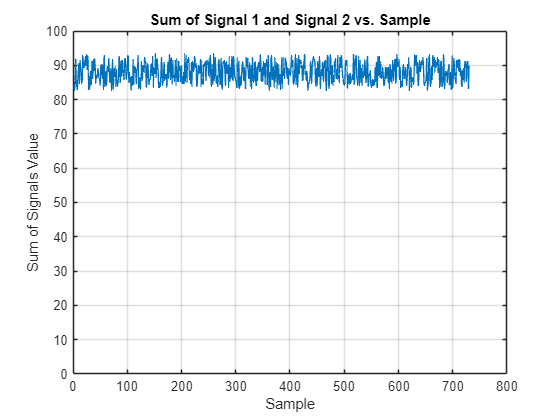

%  Sum of the two Signals
figure
plot(sample, sumSignals, 'LineWidth', 1)
title('Sum of Signal 1 and Signal 2 vs. Sample')
xlabel('Sample')
ylabel('Sum of Signals Value')
ylim([0 100])  % Scale from 0 to 100 on the y-axis
grid on

Press the Button below to Run the code in this section

### Step 3  Plot the Histograms

Plot histograms of eah of the three variables.  Title and label the x and y axes appropriately

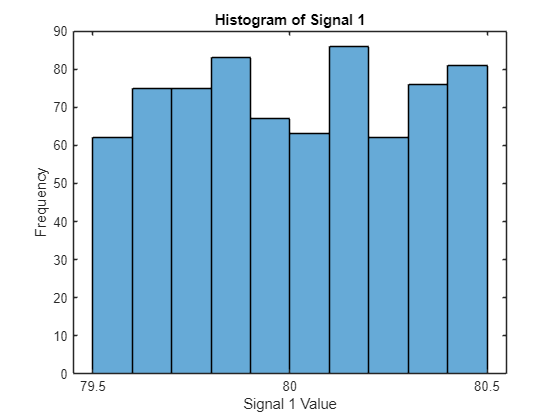

%  Plot a histogram of the signal data.


%  Solution -- Place your code here
% Histogram for Signal 1
figure
histogram(signal_1)
title('Histogram of Signal 1')
xlabel('Signal 1 Value')
ylabel('Frequency')

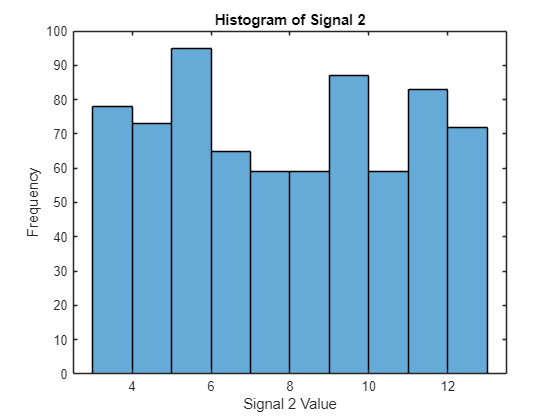


% Histogram for Signal 2
figure
histogram(signal_2)
title('Histogram of Signal 2')
xlabel('Signal 2 Value')
ylabel('Frequency')

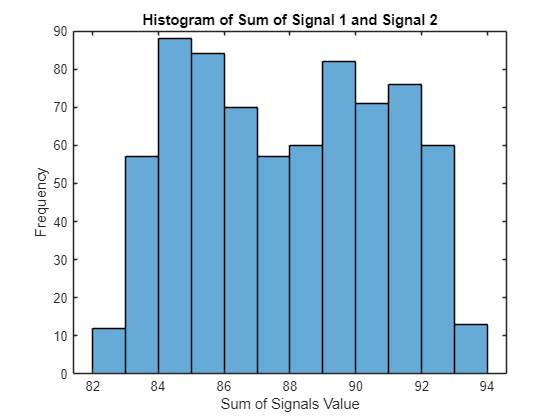


% Histogram for the Sum of Signals
figure
histogram(sumSignals)
title('Histogram of Sum of Signal 1 and Signal 2')
xlabel('Sum of Signals Value')
ylabel('Frequency')

  Press the Button below to Run the code in this section

#### Question 3

Theoretically, what should the mean of the sum of the signals be equal to? Is this the case for the data given? (exactly or approximately?) (Why, or Why not?)

By theory, the mean of the sum of two signals equals the sum of their individual means. In practice, you will observe that the measured mean of the summed signal is close to, but not exactly, the sum of each mean, since random sampling and noise introduce slight deviations.

#### Question 4

Theoretically, what should the variance of the sum of the signals be equal to? Is this the case for the data given? (exactly or approximately?) (Why, or Why not?)

For independent signals, the variance of their sum is the sum of their individual variances. Empirically, the measured variance of the sum usually matches the theoretical sum of the variances closely, although small discrepancies can arise from limited sample sizes or noise effects.

#### Question 5

Is the standard deviation of the sum of the two signals (signal_1 + signal_2)  less than,  greater than or equal to the sum of the standard deviations of the individual components signal_1, signal_2? (exactly or approximately?) (Why, or Why not?)

When two signals are independent, the standard deviation of their sum is given by the square root of the sum of their variances, which is always less than the simple sum of their individual standard deviations. This results from the properties of variance and the Pythagorean-like relationship for uncorrelated signals.

#### Question 6

What probability distribution best describes the data in the histogram of the sum of the signals (uniform, triangular, normal, other)?

The distribution of the sum of two random signals often appears more normal (Gaussian) than each individual signal alone, a result that aligns with the Central Limit Theorem, which describes how the sum of independent random variables tends to a bell-shaped distribution.

### Comments on Part 2

It is important to note that in all the analysis you’ve just done the specific values for standard deviation, mean, and so forth will change as the random numbers change. In the data file you were given a fixed set of random numbers, but in reality, each time you run such a test the random noise changes and your answers will change slightly. You are only estimating the true mean and the true standard deviation from a finite set of data points. Thus, you will have some typical error between this value and the true mean.  The typical error is the error of the estimate of the mean.

## Part 3  Creating and Computing Statistics of Random Numbers

### Step 1

In this part, you will use the MATLAB rand() function to create 12 unform random variables that range from 0 to 1 and have a mean of 0.5.  This will be done using a matrix in MATLAB.  Recall that you can create a matrix of M rows by N columns of random variables using rand(M, N).  You will then create a variable that is the sum of the first two random variable columns and an additional variable that is the sum of all 12 variables.  You will investigate the properties of those variables.

%  Create 12 uniformly distributed random variables with 2000 values for
%  each variable.  Make each variable a column with 2000 rows
%  Use the MATLAB rand( rows, columns ) function

%  Solution -- Place your code here
randData = rand(2000, 12);

   Press the Button below to Run the code in this section

### Step 2

Plot the histogram of the uniform random numbers in the first column.  Add a title and axes labels

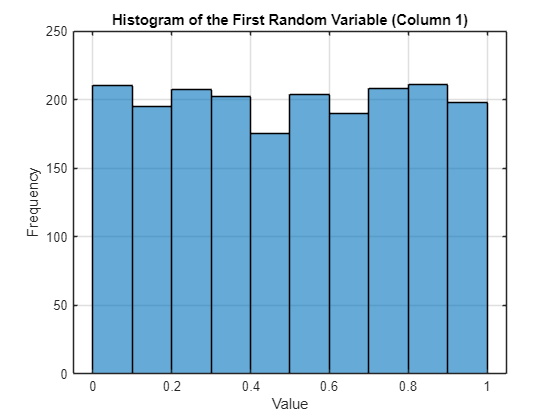

%  The histogram of the first random variable

%  Solution -- Place your code here
figure
histogram(randData(:,1))
title('Histogram of the First Random Variable (Column 1)')
xlabel('Value')
ylabel('Frequency')
grid on

   Press the Button below to Run the code in this section

### Step 3

Create a variable that is the sum of the first two columns.  Recall that you can select a single column from a matrix using the : operator.  That  is  x = M( :, 2) selects all the values in the second column of the matrix M 

%  Create a variable that is the sum of the first two columns.  
%  

%  Solution -- Place your code here
sum2 = randData(:,1) + randData(:,2);

   Press the Button below to Run the code in this section

### Step 4

Plot the histogram of the sum of the two random variables

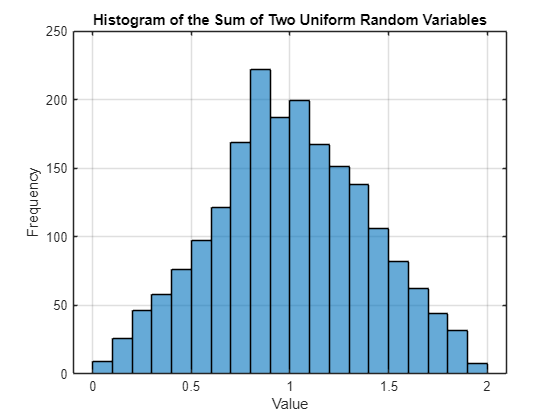

%  The histogram of the first sum of two uniform random variables

%  Solution -- Place your code here
figure
histogram(sum2)
title('Histogram of the Sum of Two Uniform Random Variables')
xlabel('Value')
ylabel('Frequency')
grid on

   Press the Button below to Run the code in this section

### Step 5

Create a variable that is the sum of all 12 random variables in the matrix.  That is the sum of all the values in each row.  The MATLAB sum function will sum all the values of a matrix across a selected DIMENSON.  You can sum the rows by taking the sum across the second dimension (that is rows). y =sum( x, 2)  You can take the sum of the values in a column by taking the sum of the first dimension (that is columns).  For example y = sum(x,1).  The result of the sum should be a matrix with 1 column of length 2000.

%  Create a variable that is the sum of all 12 random variables
%
%  Example sumRows = sum( M, 2)

%  Solution -- Place your code here
sum12 = sum(randData, 2);

   Press the Button below to Run the code in this section

### Step 6

Plot the histogram of the sum of the 12 random variables

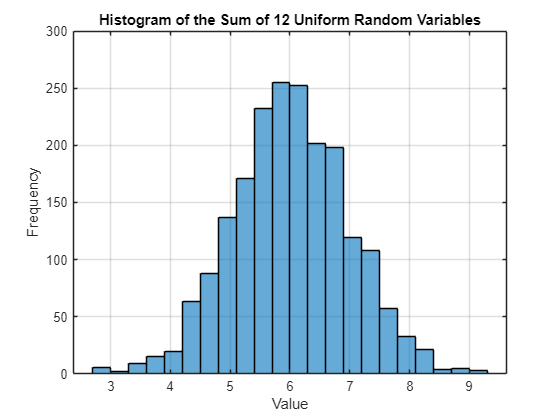

%  The histogram of the sum of 12 uniform random variables

%  Solution -- Place your code here
figure
histogram(sum12)
title('Histogram of the Sum of 12 Uniform Random Variables')
xlabel('Value')
ylabel('Frequency')
grid on

   Press the Button below to Run the code in this section

#### Question 7

Carefully compare the distributions (from the histogram) of a single uniform random variable, the sum of two uniform random variables and the sum of 12 uniform random variables.  How are each of these distributions best described (uniform, triangular, normal, other)? How does this compare to theory? What theory applies to the sum of the 12 signals?

#### Type your answer here:

A single uniform variable produces a flat distribution, the sum of two uniform variables yields a triangular distribution, and the sum of 12 uniform variables closely resembles a normal distribution. These observations match theory and illustrate the Central Limit Theorem: as more independent random variables are summed, the overall distribution approaches Gaussian.

## Part 4 Estimating Temperature Cycles

### Step 1

Load the matlab datafile from myCourses "Rochester_Average_Temp.mat".  This is data for the average daily temperature in Rochester in degress Fahrenheit over a two year period.  This will load four variables into the work space, 'sample' and 'msrdTemp', 'estTemp', 'error'

%  Clear the workspace and load the data file
clear
load data/Rochester_Average_Temp.mat
[sample, msrdTemp, estTemp, error]

ans =     1.0000   35.2000   26.3103    8.8897
    2.0000   38.9000   26.1920   12.7080
    3.0000   52.2000   26.0803   26.1197
    4.0000   40.1000   25.9751   14.1249
    5.0000   28.9000   25.8765    3.0235
    6.0000   23.1000   25.7845   -2.6845
    7.0000   14.3000   25.6991  -11.3991
    8.0000   17.3000   25.6204   -8.3204
    9.0000    3.8000   25.5484  -21.7484
   10.0000   -2.3000   25.4831  -27.7831


   Press the Button below to Run the code in this section

### Step 2

Plot the values of the measured temperature 'msrdTemp' over a two year period.  Add appropriate title and axes labels.

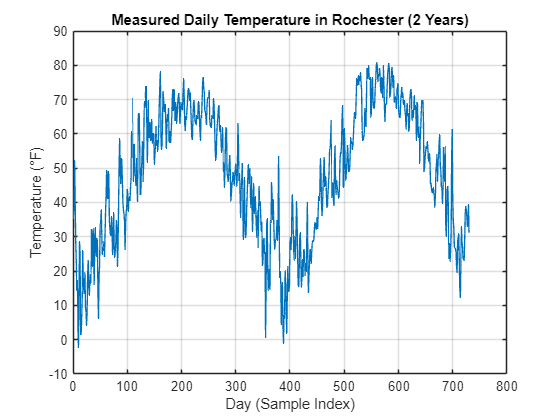

%  Plot of the average temperature in Rochester over a two year period.
%  Add a grid

%  Solution -- Place your code here
figure
plot(sample, msrdTemp, 'LineWidth', 1)
title('Measured Daily Temperature in Rochester (2 Years)')
xlabel('Day (Sample Index)')
ylabel('Temperature (°F)')
grid on

  Press the Button below to Run the code in this section

### Step 3

The daily average temperature can be estimated by a constant value of 48.2 F plus a sinusoidal variation of amplitude 23 degrees F and phase of -1.9 radians. Putting this all together, the estimated temperature is: 

Daily average temperature (F)  = 48.2+23*SIN((2*PI()*day/365)-1.9) 

The estimated daily temperature value is  already computed in the variable 'estTemp'. The error between the actual measured data and the estimated data is in the variable 'error'.

Plot the error of the estimator.  Add title and axes labels

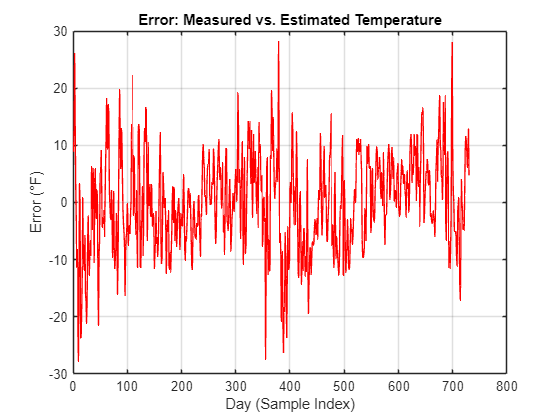

%  Plot of the error of the measured and average temperature in Rochester over a two year period.
%  Add a grid

%  Solution -- Place your code here
figure
plot(sample, error, 'LineWidth', 1, 'Color', 'r')
title('Error: Measured vs. Estimated Temperature')
xlabel('Day (Sample Index)')
ylabel('Error (°F)')
grid on

  Press the Button below to Run the code in this section

### Step 4

Plot the histogram of the error in temperature.  Add titles and label the axes.

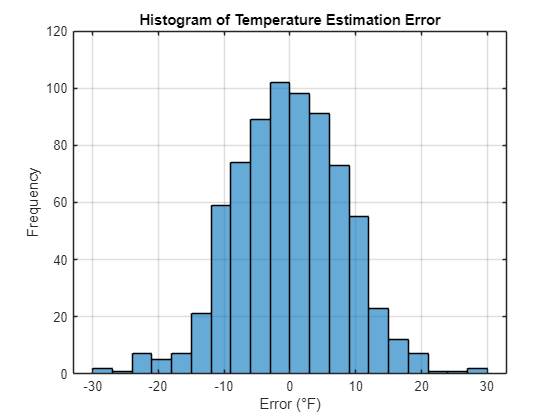

%  The histogram of the temperature error

%  Solution -- Place your code here
figure
histogram(error)
title('Histogram of Temperature Estimation Error')
xlabel('Error (°F)')
ylabel('Frequency')
grid on

   Press the Button below to Run the code in this section

### Step 5

Compute the standard deviation of the temperature error

%  The standard deviation of the error temperatures

%  Solution -- Place your code here
stdError = std(error);
disp(['Standard Deviation of the Error = ', num2str(stdError), ' °F'])

Standard Deviation of the Error = 8.326 °F


   Press the Button below to Run the code in this section

#### Question 8

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?

#### Type your answer here:

In the temperature estimation example, the error (measured minus estimated temperature) is often well-approximated by a normal distribution, with values centered around zero. Real-world noise and modeling imperfections typically combine in a way that leads to a bell-shaped spread of error values.

### Step 6

If the estimator predicts that the temperature today will be 55 degrees, what is the signal to noise ratio of this estimate, Given that the standard deviation of the error was the value you just calculated?   What is the value of the signal considered to be?

%  Signal to noise ratio calculation

%  Solution -- Place your code here
predictedTemp = 55;
SNR = predictedTemp / stdError;

disp(['Signal-to-Noise Ratio = ', num2str(SNR), ' (ratio)'])

Signal-to-Noise Ratio = 6.6058 (ratio)


   Press the Button below to Run the code in this section

## Part 5  Quantization Noise -- Uncorrelated Signal

### Step 1

Load the matlab datafile from myCourses "Quantized_Signal_1.mat".  This is data for a continuous sinusoidal signal and one that is quantized with a quantization size of 1.  Four variables are loaded into the MATLAB workspace

sample -- the sample number

conSignal -- The high resolution continuous sinusoidal signal

qSignal -- The quantized sinusoidal signal

error -- The error between the continuous signal and the quantized signal

The formula for the sinewave is: = 127.5 + 127.5*sin( sample / 10 )

The sinewave is **not** tightly correlated with the sampling frequency. 

Plots of the signals are made for you below

%  Clear the workspace and load the data file
clear
load data/Quantized_Signal_1.mat
[sample, conSignal, qSignal, error]

ans =          0  127.5000  128.0000   -0.5000
    1.0000  140.2288  140.0000    0.2288
    2.0000  152.8303  153.0000   -0.1697
    3.0000  165.1788  165.0000    0.1788
    4.0000  177.1508  177.0000    0.1508
    5.0000  188.6268  189.0000   -0.3732
    6.0000  199.4919  199.0000    0.4919
    7.0000  209.6378  210.0000   -0.3622
    8.0000  218.9629  219.0000   -0.0371
    9.0000  227.3742  227.0000    0.3742


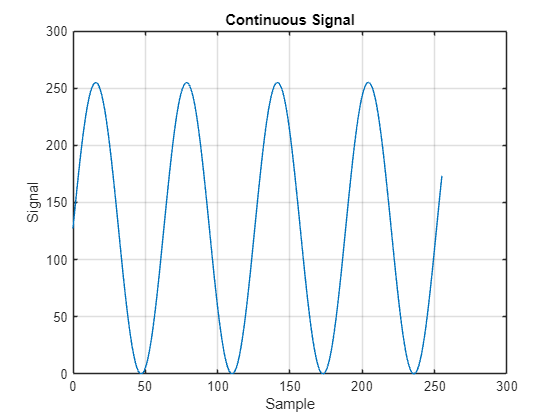

%  Plot the signals
figure
plot(sample, conSignal)
grid on
title('Continuous Signal')
xlabel('Sample')
ylabel('Signal')

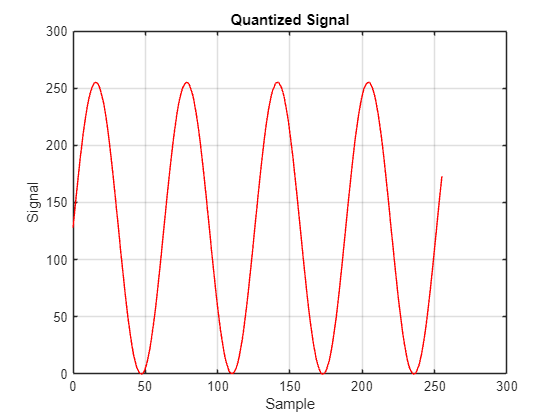

figure
plot(sample, qSignal,'r')
grid on
title('Quantized Signal')
xlabel('Sample')
ylabel('Signal')

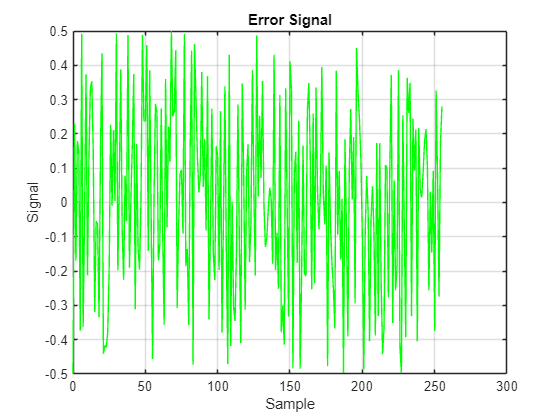

figure
plot(sample, error,'g')
grid on
title('Error Signal')
xlabel('Sample')
ylabel('Signal')

   Press the Button below to Run the code in this section

### Step 2

Plot a histogram of the quantization error using the histogram bins edges given in the variable 'binEdges' in the code section.  The option to add bin edges is:

histogram( x, binEdges )

Then create a  historgram showing the cumulative values by adding the PropertyName 'Normalization' with a value of 'cdf'.  This represents the cumulative density function of the data.

example

histogram(x, binEdges, 'Normalization','cdf')

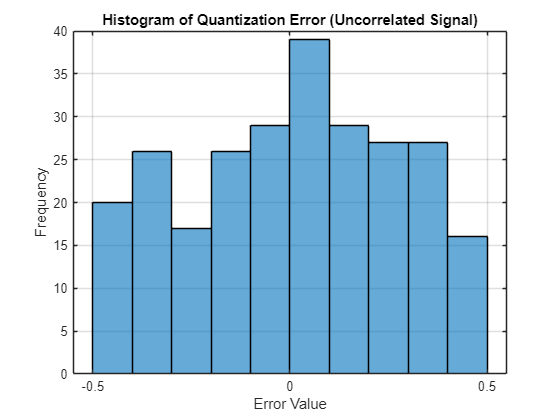

%  Plot the histogram of the quantization error

binEdges = -0.5:0.1:0.5;

% 1) Regular Histogram
figure
histogram(error, binEdges)
title('Histogram of Quantization Error (Uncorrelated Signal)')
xlabel('Error Value')
ylabel('Frequency')
grid on

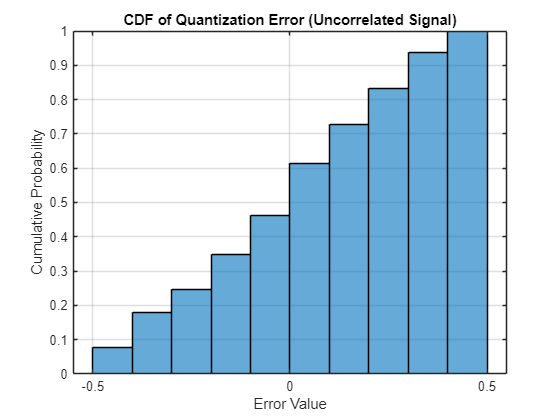

% 2) CDF (Cumulative Density Function)
figure
histogram(error, binEdges, 'Normalization','cdf')
title('CDF of Quantization Error (Uncorrelated Signal)')
xlabel('Error Value')
ylabel('Cumulative Probability')
grid on

   Press the Button below to Run the code in this section

#### Question 11

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?  What do you observe about the cumulative density function and how does it relate to the histogram of the data?

#### Type your answer here:

When the signal is uncorrelated with the sampling rate, the quantization error tends to be uniformly distributed between -0.5 and +0.5, producing a flat histogram. Its cumulative distribution function (CDF) is therefore a straight line ramp, consistent with a uniform distribution.

## Part 6  Quantization Noise -- Correlated Signal

### Step 1

Load the matlab datafile from myCourses "Quantized_Signal_2.mat".  This is data for a continuous sinusoidal signal and one that is quantized with a quantization size of 1.  Four variables are loaded into the MATLAB workspace

sample -- the sample number

conSignal -- The high resolution continuous sinusoidal signal

qSignal -- The quantized sinusoidal signal

error -- The error between the continuous signal and the quantized signal

The formula for the sinewave is: = 127.5 + 127.5*sin( 2*pi*sample / 64 )

The sinewave **is** tightly correlated with the sampling frequency. 

Plots of the signals are made for you below

%  Clear the workspace and load the data file
clear
load data/Quantized_Signal_2.mat
[sample, conSignal, qSignal, error]

ans =          0  127.5000  128.0000   -0.5000
    1.0000  139.9972  140.0000   -0.0028
    2.0000  152.3740  152.0000    0.3740
    3.0000  164.5113  165.0000   -0.4887
    4.0000  176.2921  176.0000    0.2921
    5.0000  187.6031  188.0000   -0.3969
    6.0000  198.3352  198.0000    0.3352
    7.0000  208.3851  208.0000    0.3851
    8.0000  217.6561  218.0000   -0.3439
    9.0000  226.0588  226.0000    0.0588


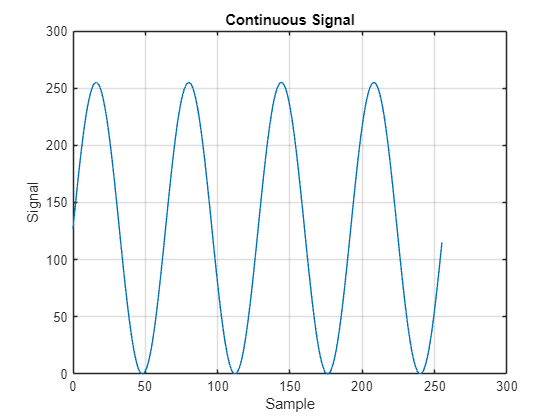

%  Plot the signals
figure
plot(sample, conSignal)
grid on
title('Continuous Signal')
xlabel('Sample')
ylabel('Signal')

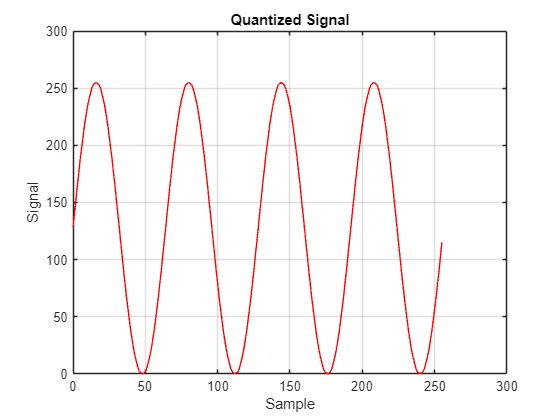

figure
plot(sample, qSignal,'r')
grid on
title('Quantized Signal')
xlabel('Sample')
ylabel('Signal')

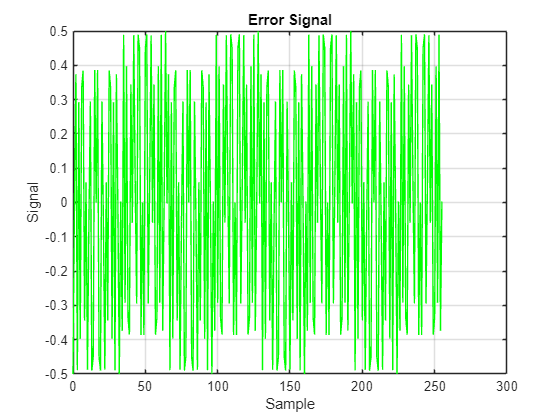

figure
plot(sample, error,'g')
grid on
title('Error Signal')
xlabel('Sample')
ylabel('Signal')

   Press the Button below to Run the code in this section

### Step 2

Plot a histogram of the quantization error using the histogram bins edges given in the variable 'binEdges' in the code section.  The option to add bin edges is:

histogram( x, binEdges )

Then create a  historgram showing the cumulative values by adding the PropertyName 'Normalization' with a value of 'cdf'.  This represents the cumulative density function of the data.

example

histogram(x, binEdges, 'Normalization','cdf')

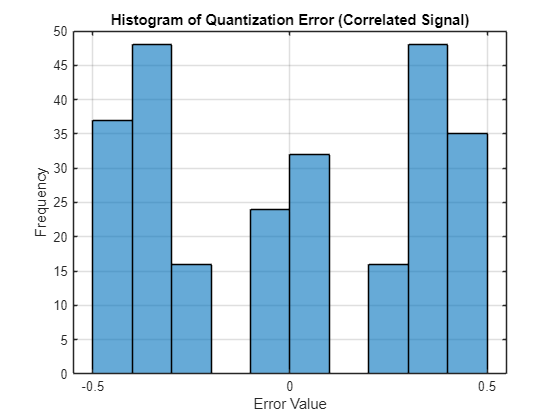

%  Plot the histogram of the quantization error

binEdges = -0.5:0.1:0.5;

% Regular Histogram
figure
histogram(error, binEdges)
title('Histogram of Quantization Error (Correlated Signal)')
xlabel('Error Value')
ylabel('Frequency')
grid on

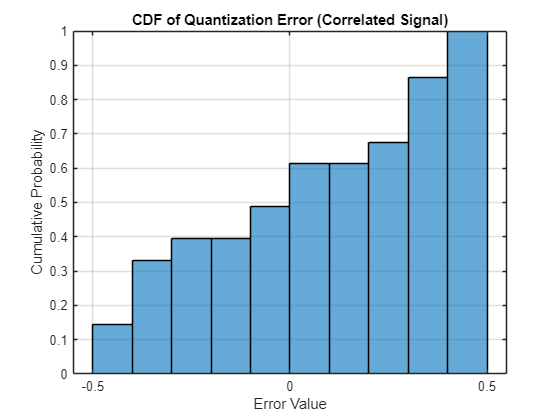

% CDF Plot
figure
histogram(error, binEdges, 'Normalization','cdf')
title('CDF of Quantization Error (Correlated Signal)')
xlabel('Error Value')
ylabel('Cumulative Probability')
grid on

   Press the Button below to Run the code in this section

#### Question 12

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?

#### Type your answer here:

In the correlated quantization scenario, the distribution of the quantization error is not uniform and may show clustering around certain values due to repeated sampling at the same phases of the waveform. This correlation disrupts the flat shape seen in the uncorrelated case.

#### Question 13

Are the distributions of the quantization error significantly different or largely the same between the correlated and the uncorrelated signals?

#### Type your answer here:

Quantization errors differ significantly between uncorrelated and correlated signals. The uncorrelated signal’s error distribution looks uniform, while the correlated signal’s error distribution can have a multi-peaked or otherwise non-uniform shape, because the sampling instants consistently fall on similar points in the wave’s cycle.

When the sample rate and the signal are correlated with one another, the distribution of the quantization error may not look uniform as it does when the sample and the signal rate are uncorrelated with one another.

## Part 7  Typical Error

When we take multiple samples from a random process with noise the individual sample values will vary in value.  The mean of all the samples that we take will be an estimate of the true mean of the process.  This estimate of the mean has some amount of error to the true mean of the process.  We define a quantity called the "typical" error.  We can find the typical error by computing multiple estimates of the mean and finding the standard deviation of all those estimates.  The standard deviation is what we call the typical error of the estimate.

We can decrease the typical error (decrease the standard deviation) of the estimate by including more samples in our estimate of the mean.  For example the typical error of the estimate when I use 100 samples of the process in computing the estimate of the mean will be smaller than the typical error when I use 10 samples of the process in computing the estimate of the mean.

The typical error or standard deviation of the estimate improves inversely proportional to the square root of the number of samples used in the estimate.  That is:


$$\sigma_{n} = \frac{\sigma_{process}}{\sqrt{n}}$$


where $\sigma_{n}
$ is the standard deviation of the mean estimate when using n samples to compute the estimate.  This equation indicates that the standard deviation of the estimate using N samples is equal to the process standard deviation divided by the square root of the number of samples in the estimate.

### Step 1

In this part of the lab you will simulate computing the estimate of the mean of a process using 1 sample from that process.  You will calculate the typical error (using the standard deviation). Then you will simulate computing the estimate of the mean of the process using a larger number of samples to reduce the typical error to a specified amount.  You will determine the number of samples required to reduce the typical error to an acceptable level.  The code for the first step is done for you.  Take a look to see how it is done.

%  Clear the workspace 
clear

%  Define some constants of the process

% Process parameters
%
% True process mean -- The signal is a fixed value that has a fixed true mean
%
trueMeanProcess = 3.5;

%  Standard deviation of the process.  The process has noise on it that is
%  normally distributed.  The value of the standard deviation is .001.
sigmaProcess  = .001;

%  Number of trials -- The number of trials is the number of estimates of the mean that you will compute
%  This is not the number of samples used in the mean estimate, just the number
%  of estimates.  We look at a large number of estimates to see how they
%  differ from one another.

numTrials = 1000; 


%  !!!!  Copy from here for Step 3 !!!!

%  Number of samples taken for each estimate
%  This is the number of samples that are used to compute the estimate.
%  We'll start with by using one sample to estimate the process mean

numSamplesPerEstimate = 1;



%  Compute 'numTrials' estimates of the mean of the process.  For each trial use numSamples to compute the
%  estimate.  Use a 'for' loop for this (not very MATLABian however :-(  )

%  Clear the matrix of estimates of the mean that will be computed.  We'll
%  save all the values that we estimate
meanEstimate = zeros(numTrials,1);

for iTrial = 1:numTrials
    
    %  Create numSamplesPerEstimate samples of the process    
    processSamples = sigmaProcess * randn(numSamplesPerEstimate,1) + trueMeanProcess;
    
    % Now take the average of those samples
    meanEstimate(iTrial) = mean(processSamples);

    
end

%  Find the typical error of the mean estimate.  Plot a histogram

typicalError = std(meanEstimate);
disp(['Typical Error (std) using 1 sample/estimate = ', num2str(typicalError)]);

Typical Error (std) using 1 sample/estimate = 0.0010161


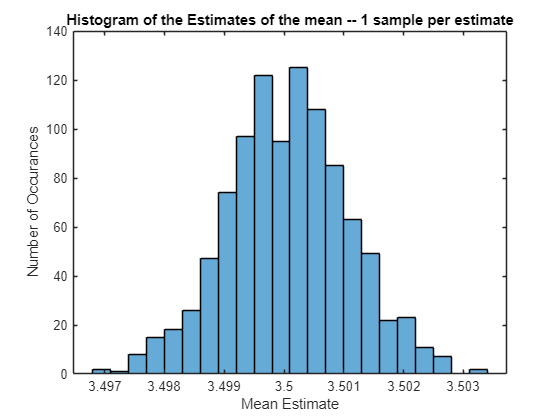

figure
histogram(meanEstimate)
title('Histogram of the Estimates of the mean -- 1 sample per estimate')
xlabel('Mean Estimate');
ylabel('Number of Occurances');


%  !!!! Stopy Copying Here for Step 3 !!!!

   Press the Button below to Run the code in this section

### Step 2

Calculate the number of samples required to compute the estimate of the mean in order to keep the typical error of the mean estimate below $100\times10^{-6}
$ .  The standard deviation of the mean estimate using 1 sample from the process for each estimate should be $1\times10^{-3}
$.  Is that the value that you computed?

Recall that the typical error of the estimate of the mean is:


$$typical\ error=\sigma_{estimate} =\sigma /\sqrt{N}$$


Solve for the value of N, the number of samples to use in the mean estimate computation


$$N = (\frac{\sigma_{process}}{\sigma_{est}})^2$$


desiredError = 0.0002;  % The maximum allowed typical error

% We already have sigmaProcess = 0.001 from above
N_required = (sigmaProcess / desiredError)^2;

disp(['To achieve a typical error below ', num2str(desiredError), ...
      ', you need more than ', num2str(N_required), ' samples per estimate.']);

To achieve a typical error below 0.0002, you need more than 25 samples per estimate.


   Press the Button below to Run the code in this section

### Step 3

Estimate the true mean using the number of samples that you computed above. Copy the code from above that finds the estimate of the mean from the process using 1 sample from the process.  Then change the paramters to use the number of samples that you computed above.  

Change the name of the variable meanEstimate to something different so that you can save both sets of values and plot both histograms on top of one another for comparison

numSamplesPerEstimate2 = ceil(N_required);  % Round up to nearest integer

meanEstimate2 = zeros(numTrials,1);

for iTrial = 1:numTrials
    
    processSamples = sigmaProcess * randn(numSamplesPerEstimate2,1) + trueMeanProcess;
    meanEstimate2(iTrial) = mean(processSamples);
    
end

% Compute the new typical error
typicalError2 = std(meanEstimate2);

disp(['Using ', num2str(numSamplesPerEstimate2), ' samples/estimate:']);

Using 25 samples/estimate:


disp(['Typical Error (std) = ', num2str(typicalError2)]);

Typical Error (std) = 0.00020958


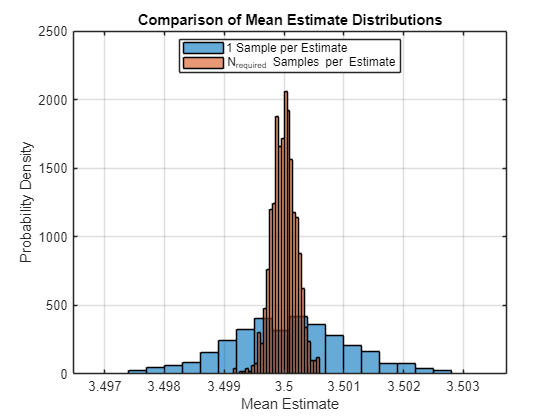


% Overplot histograms for comparison:
figure
histogram(meanEstimate, 'Normalization','pdf')
hold on
histogram(meanEstimate2, 'Normalization','pdf')
hold off
legend('1 Sample per Estimate','N_{required} Samples per Estimate','Location','best')
title('Comparison of Mean Estimate Distributions')
xlabel('Mean Estimate')
ylabel('Probability Density')
grid on

   Press the Button below to Run the code in this section

### Question 14

Describe the similarities and differences in the histograms of the mean estimates when you use 1 sample of the process for the estimate vs the number of samples that you computed to reduce the typcial error of the estimate.  What is the significance in the differences between the histograms?  What is the significance of the similarities between the two histograms?

Did the typical error of the estimate decrease to the specified values after changing the number of samples for each estimate?

Did the process change, or did the way you were estimating the mean of the process change?

#### Type your answer here:

Using only one sample per estimate results in a wide spread of mean estimates, whereas using many samples per estimate narrows the distribution significantly. The typical error indeed decreases to near the desired threshold, even though the process itself remains unchanged; only the method of estimating its mean (the number of samples averaged) is different.

# Report Requirements

Save this file as a PDF file (FILE/Export to pdf) or first export to Word then save the Word file as a PDF.  Submit your completed MATLAB Live Script file and the PDF to the Assignments section of myCourses for Lab2.  Review your PDF file before submitting to insure that all your graphs have rendered correctly.  

Make sure that you include your team member names at the top of this file.

Make sure that you use the file naming convention with the Lab section and group name for example: Lab01_GroupName_Lab2.mlx